Modelling a Grain boundary

- Matlab 

Load into Matlab the epos & rangeFig -> decomposed pos file

spec = gco;
posIn = posToTable;
pos = posAllocateRange(posIn, rangesExtractFromMassSpec(spec), 'decompose');
nnz(pos.atom == 'C'); % number of C atoms


Create a hull of the dataset

hull = patchCreateSampledAlphaHull(pos, 10, 1e5);
patchToObj(hull,'hull'); % export the hull to an .obj object
posToObj(pos, {'C'}); % export all of the C atoms in the data set as .obj 

2. Blender

Load the hull & the C atoms into Blender -> create a plane -> subdivide the plane -> move & rotate the plane so that it fits the GB -> delete all of the points of the plane that are outside the hull -> add triangles at the outside of the plane so that it fits the hull better

Import the hull & the atoms

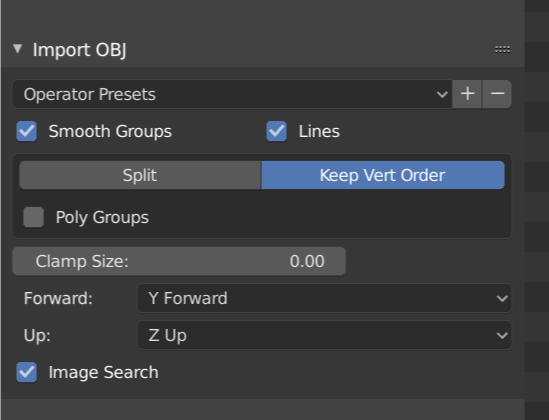

gedrückte mittlere Maustaste bewegt die Szene

Exportiere die Korngrenze als .obj mit folgendne Häckchen

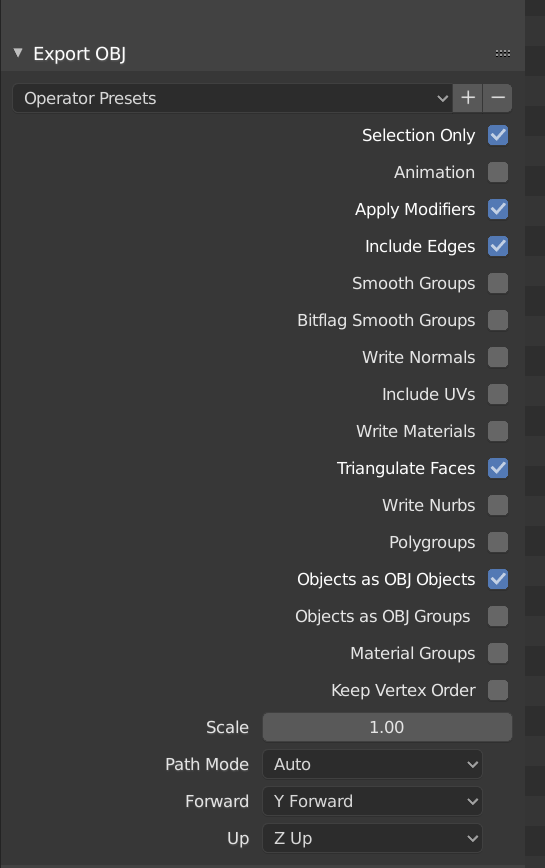

Export the plane as an .obj (selection only, 

3. Matlab

Import the GB Plane into Matlab 

obj = obj2patch();
GB.vertices = obj.vertices;
GB.faces = obj.objects{1}.vertices;
patch(GB, 'FaceColor', 'r'); % plots it into the figure with the hull

GB2 = patchStretchToHull(GB, hull); %Grain boundary model stretched to the boundary
patch(GB2, 'FaceColor', 'r'); % plots the grain boundary in the hull (the older one GB must be deleted before);

D = pos(pos.atom =='D',:); %Create a pos file just with the D atoms
GB3 = patchSnapToAtomPositions(GB2,[D.x, D.y, D.z, D.mc],10);
patch(GB3, 'FaceColor', 'r'); % plot the grain boundary in the hull

Now we have fit our grain boundary model to the actual positions of the grain boundaries

Now we can calculate an interface ExcessValue

patchCreateExcessValue(D, pos, GB3);

Convert a pos table in a double 

pos_old(:,1) = posRaw.ionIdx;
pos_old(:,2) = posRaw.x;
pos_old(:,3) = posRaw.y;
pos_old(:,4) = posRaw.z;
pos_old(:,5) = posRaw.mc;
pos_old(:,6) = posRaw.tof;
pos_old(:,7) = posRaw.VDC;
pos_old(:,8) = posRaw.VP;
pos_old(:,9) = posRaw.detx;
pos_old(:,10) = posRaw.dety;
pos_old(:,11) = posRaw.deltaP;
pos_old(:,12) = posRaw.multi;
pos_old(:,13) = posRaw.atomNum;
pos_old(:,14) = posRaw.ion;
pos_old(:,15) = posRaw.chargeState;



pos_H = pos(pos.ion == 'H',:);
pos_old_D(:,1) = pos_H.ionIdx;
pos_old_D(:,2) = pos_H.x;
pos_old_D(:,3) = pos_H.y;
pos_old_D(:,4) = pos_H.z;
pos_old_D(:,5) = pos_H.mc;
pos_old_D(:,6) = pos_H.tof;
pos_old_D(:,7) = pos_H.VDC;
pos_old_D(:,8) = pos_H.VP;
pos_old_D(:,9) = pos_H.detx;
pos_old_D(:,10) = pos_H.dety;
pos_old_D(:,11) = pos_H.deltaP;
pos_old_D(:,12) = pos_H.multi;
pos_old_D(:,13) = pos_H.atomNum;
pos_old_D(:,14) = pos_H.ion;
pos_old_D(:,15) = pos_H.chargeState;

pos_old_D(:,1) = pos_D.ionIdx;
pos_old_D(:,2) = pos_D.x;
pos_old_D(:,3) = pos_D.y;
pos_old_D(:,4) = pos_D.z;
pos_old_D(:,5) = pos_D.mc;
pos_old_D(:,6) = pos_D.tof;
pos_old_D(:,7) = pos_D.VDC;
pos_old_D(:,8) = pos_D.VP;
pos_old_D(:,9) = pos_D.detx;
pos_old_D(:,10) = pos_D.dety;
pos_old_D(:,11) = pos_D.deltaP;
pos_old_D(:,12) = pos_D.multi;
pos_old_D(:,13) = pos_D.atomNum;
pos_old_D(:,14) = pos_D.ion;
pos_old_D(:,15) = pos_D.chargeState;